%{
ES115 Engineering Computer Applications
Module 8 Project: Package Delivery Time Estimator

Author: Zulaikha Khan  
Instructor: Lynroy Grant  
Date: March 28, 2026  

Purpose:
This project models the time required to deliver a package based on distance.
A linear equation is used to represent travel time combined with a fixed
handling time. The goal is to calculate delivery time for different distances,
categorize delivery durations, and display the results in both table and
graph form.

Inputs (Knowns):
- Distance values (d) from 0 to 40 miles
- Speed = 30 miles per hour
- Handling time = 10 minutes
- Linear model form: T(d) = md + b
    • m = 60 / speed (minutes per mile)
    • b = handling time

Outputs (Unknowns):
- Delivery time for each distance
- Categorization of delivery time (short, medium, long)
- Table of distance, time, and category
- Graph of delivery time vs distance

Engineering Workflow and Algorithms:
- Define distance values over the given range
- Convert speed into minutes per mile
- Create linear time model using slope and intercept
- Compute delivery time for each distance
- Categorize delivery times based on conditions
- Store results in a table
- Plot delivery time vs distance

MATLAB Tools / Functions Used:
- plot() for graphing
- table() for organizing data
- for-loop for assigning categories
- if / elseif conditions for classification
- strings() to store text labels
- disp() for displaying results

Reflection After Completing the Project:
- I learned how to build a linear model from real-world parameters like
  speed and handling time and how to interpret the results.
- I also practiced using loops and conditional statements to classify data.
- If I were to improve this, I would make the categories more detailed or
  include additional factors like traffic or delays.
- Difficulty Rating: 4/10 — this project was straightforward, but combining
  modeling with classification required attention.
%}
 


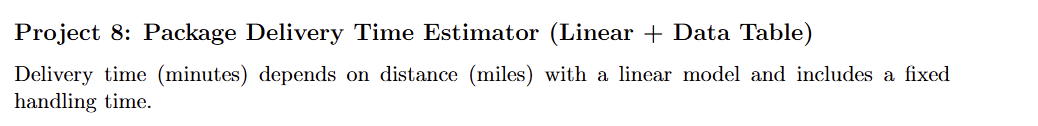


clear; clc; close all; 
 
% ---------------------------- 
% Define distance values (miles) 
d = 0:1:40; 
 
% ---------------------------- 
% Choose realistic parameters 
 
speed = 30; % miles per hour 
handling = 10; % minutes (fixed handling time) 
 
% Convert speed to minutes per mile 
m = 60 / speed; % minutes per mile 
b = handling; % intercept (handling time) 
 
% ---------------------------- 
% Time model 
T = m*d + b; 
 
% ---------------------------- 
% Create interpretation labels 
labels = strings(length(d),1); 
 
for i = 1:length(d) 
if T(i) < 30 
labels(i) = "short"; 
elseif T(i) < 60 
labels(i) = "medium"; 
else 
labels(i) = "long"; 
end 
end 
 
% ---------------------------- 
% Create table 
Table = table(d', T', labels, 'VariableNames', {'Distance_miles','Time_minutes','Category'}); 
 
disp('Delivery Time Table:'); 

Delivery Time Table:


disp(Table(1:15,:)); % show first 15 rows 

    Distance_miles    Time_minutes    Category
    ______________    ____________    ________

           0               10         "short" 
           1               12         "short" 
           2               14         "short" 
           3               16         "short" 
           4               18         "short" 
           5               20         "short" 
           6               22         "short" 
           7               24         "short" 
           8               26         "short" 
           9               28         "short" 
          10               30         "medium"
          11               32         "medium"
          12               34         "medium"
          13               36         "medium"
          14               38         "medium"



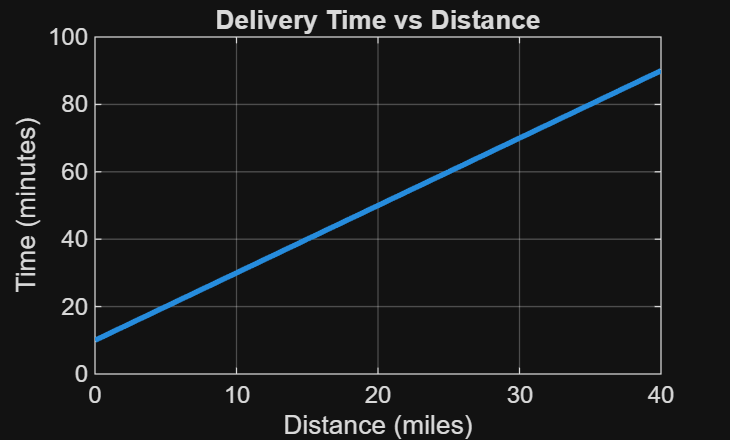

 
% ---------------------------- 
% Plot time vs distance 
figure; 
plot(d, T, 'LineWidth', 2); 
 
title('Delivery Time vs Distance'); 
xlabel('Distance (miles)'); 
ylabel('Time (minutes)'); 
grid on; 